# Classifying Urban Sounds8K Dataset using Using Wavelet Analysis and Deep Learning

Kevin Chng

## Overview :

            For this example, we are going to classify Urban sounds dataset using wavelet analysis and deep learning.

            For this project we will use a dataset called Urbansound8K. The dataset contains 8732 sound excerpts (<=4s) of urban sounds from 10 classes, which are:

- Air Conditioner

- Car Horn

- Children Playing

- Dog bark

- Drilling

- Engine Idling

- Gun Shot

- Jackhammer

- Siren

- Street Music

The accompanying metadata contains a unique ID for each sound excerpt along with it's given class name. A sample of this dataset is included with the accompanying git repo and the full dataset can be downloaded from [here](https://urbansounddataset.weebly.com/urbansound8k.html).    

## **Highlights : **

- transforming audio signal from 1D to 2D for [imageDatastore](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html)

- Extract features using Wavelet Analysis

- Train machine learning model using pretrained neural network

- deploy machine learning model to embedded devices or desktop application

## **Product Focus :**

- MATLAB

- Audio Toobox

- Deep Learning Toolbox

- Signal Processing Toolbox

- Wavelet Toolbox

**Written at 7 Jan 2020**

## **Load Data - Audiodatastore**

rng(1)
datafolder = "UrbanSound8K/structure";

ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames');

## Convert data to 2D Scallogram

- Save a signal data to 2D scallogram image

% save Image to folder, and create the relevant subfolder
datafolder_scallogram = "UrbanSound8K/structure_Scallogram";
catego=categories(ads.Labels);
for i = 1:1:length(catego)
    imgLoc = fullfile(datafolder_scallogram,char(catego{i}));
    mkdir(imgLoc)
end

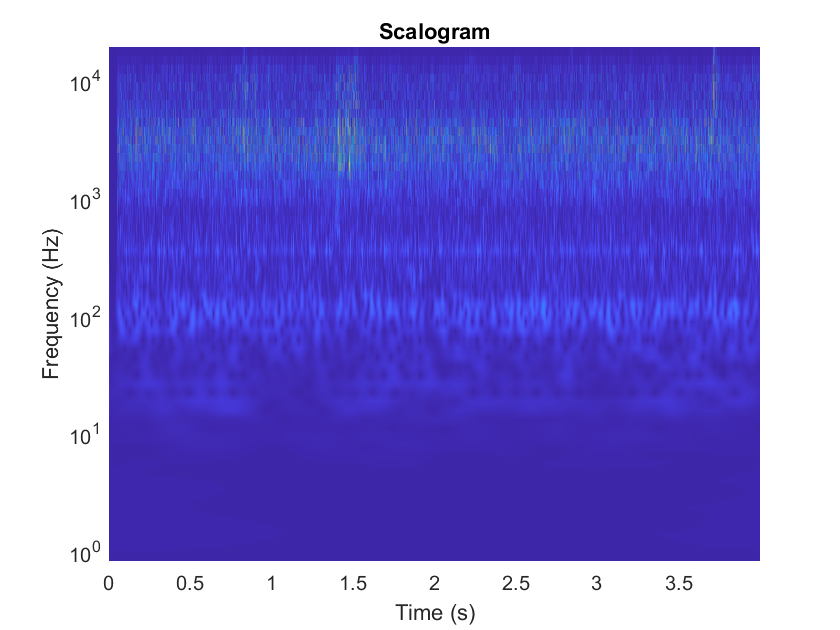

Fs = 44100;
sig = audioread(ads.Files{1});
fb = cwtfilterbank('SignalLength',length(sig),...
    'SamplingFrequency',Fs,...
    'VoicesPerOctave',4);
[cfs,frq] = wt(fb,sig);
t = (0:length(sig)-1)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)')

helperCreateRGBfromTF(ads,datafolder_scallogram)

## **Divide into Training, Validation and Testing Data**

Load the scalogram images as an image datastore. The [`imageDatastore`](https://ww2.mathworks.cn/help/matlab/ref/matlab.io.datastore.imagedatastore.html) function automatically labels the images based on folder names and stores the data as an ImageDatastore object. An image datastore enables you to store large image data, including data that does not fit in memory, and efficiently read batches of images during training of a CNN.

allImages = imageDatastore(datafolder_scallogram,...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng(1)
[imgsTrain,imgsValidation,imgsTest] = splitEachLabel(allImages,0.6,0.2,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 5238


countEachLabel(imgsTrain)

ans = 10×2 table
         Label          Count
    ________________    _____

    Air Conditioner      600 
    Car Horn             257 
    Children Playing     600 
    Dog Bark             600 
    Drilling             600 
    Engine Idling        600 
    Gun Shot             224 
    Jackhammer           600 
    Siren                557 
    Street Music         600 


disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

Number of validation images: 1747


countEachLabel(imgsValidation)

ans = 10×2 table
         Label          Count
    ________________    _____

    Air Conditioner      200 
    Car Horn              86 
    Children Playing     200 
    Dog Bark             200 
    Drilling             200 
    Engine Idling        200 
    Gun Shot              75 
    Jackhammer           200 
    Siren                186 
    Street Music         200 


disp(['Number of validation images: ',num2str(numel(imgsTest.Files))]);

Number of validation images: 1747


countEachLabel(imgsTest)

ans = 10×2 table
         Label          Count
    ________________    _____

    Air Conditioner      200 
    Car Horn              86 
    Children Playing     200 
    Dog Bark             200 
    Drilling             200 
    Engine Idling        200 
    Gun Shot              75 
    Jackhammer           200 
    Siren                186 
    Street Music         200 


## Load Pretrained Network

- Our image size is 224,224,3. If you use other neural network with different input size, refer to [imageDataAugmenter ](https://www.mathworks.com/help/deeplearning/ref/imagedataaugmenter.html)how to resize the image for different neural network.

net = googlenet;

Use `analyzeNetwork` to display an interactive visualization of the network architecture and detailed information about the network layers.

analyzeNetwork(net)

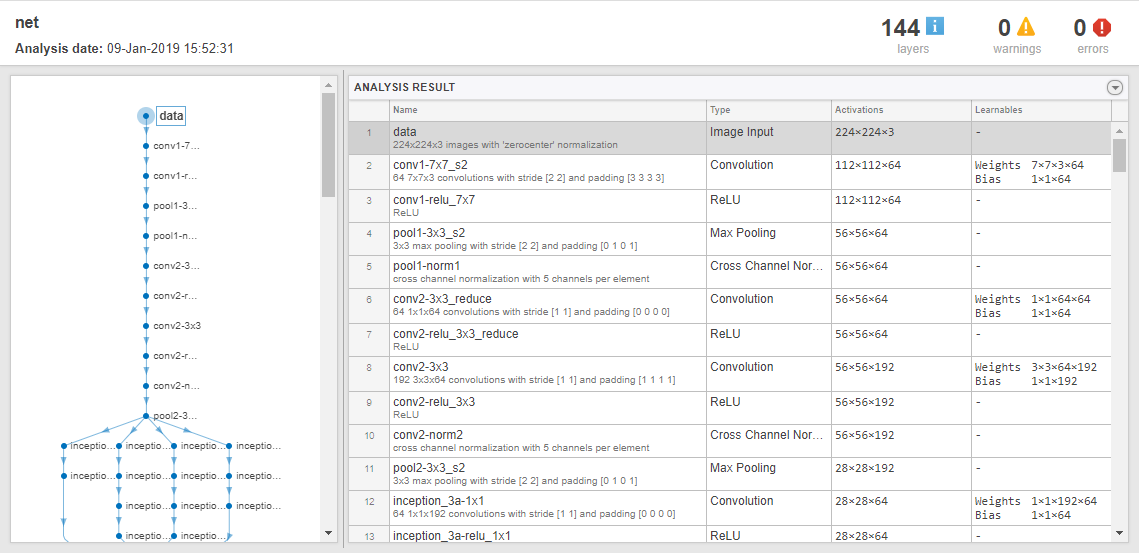

The first element of the `Layers` property of the network is the image input layer. For a GoogLeNet network, this layer requires input images of size 224-by-224-by-3, where 3 is the number of color channels. Other networks can require input images with different sizes. For example, the Xception network requires images of size 299-by-299-by-3.

net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


inputSize = net.Layers(1).InputSize;

## Replace Final Layers

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 

ans =   1x2 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (10 in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. 

numClasses = numel(categories(imgsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

To check that the new layers are connected correctly, plot the new layer graph and zoom in on the last layers of the network.

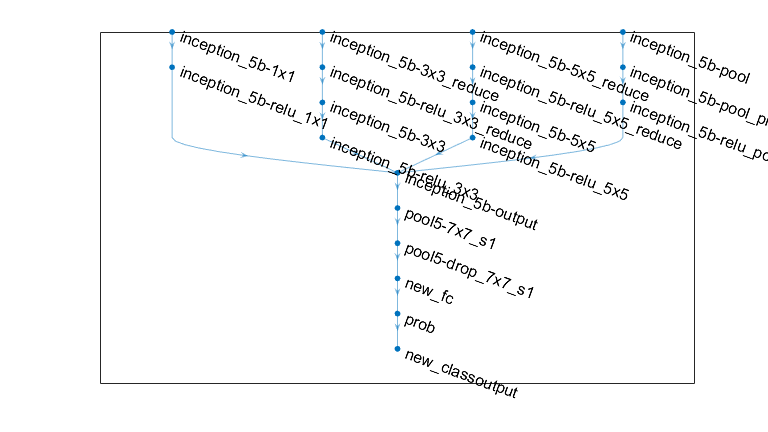

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

## Train Network 

Specify the training options. Set `InitialLearnRate` to a small value to slow down learning in the transferred layers that are not already frozen. In the previous step, you increased the learning rate factors for the last learnable layer to speed up learning in the new final layers. This combination of learning rate settings results in fast learning in the new layers, slower learning in the middle layers, and no learning in the earlier, frozen layers. 

Specify the number of epochs to train for. When performing transfer learning, you do not need to train for as many epochs. An epoch is a full training cycle on the entire training data set. Specify the mini-batch size and validation data. Compute the validation accuracy once per epoch.

miniBatchSize = 16;
valFrequency = floor(numel(imgsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imgsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the network using the training data. By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, `trainNetwork` uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`. Because the data set is so small, training is fast.

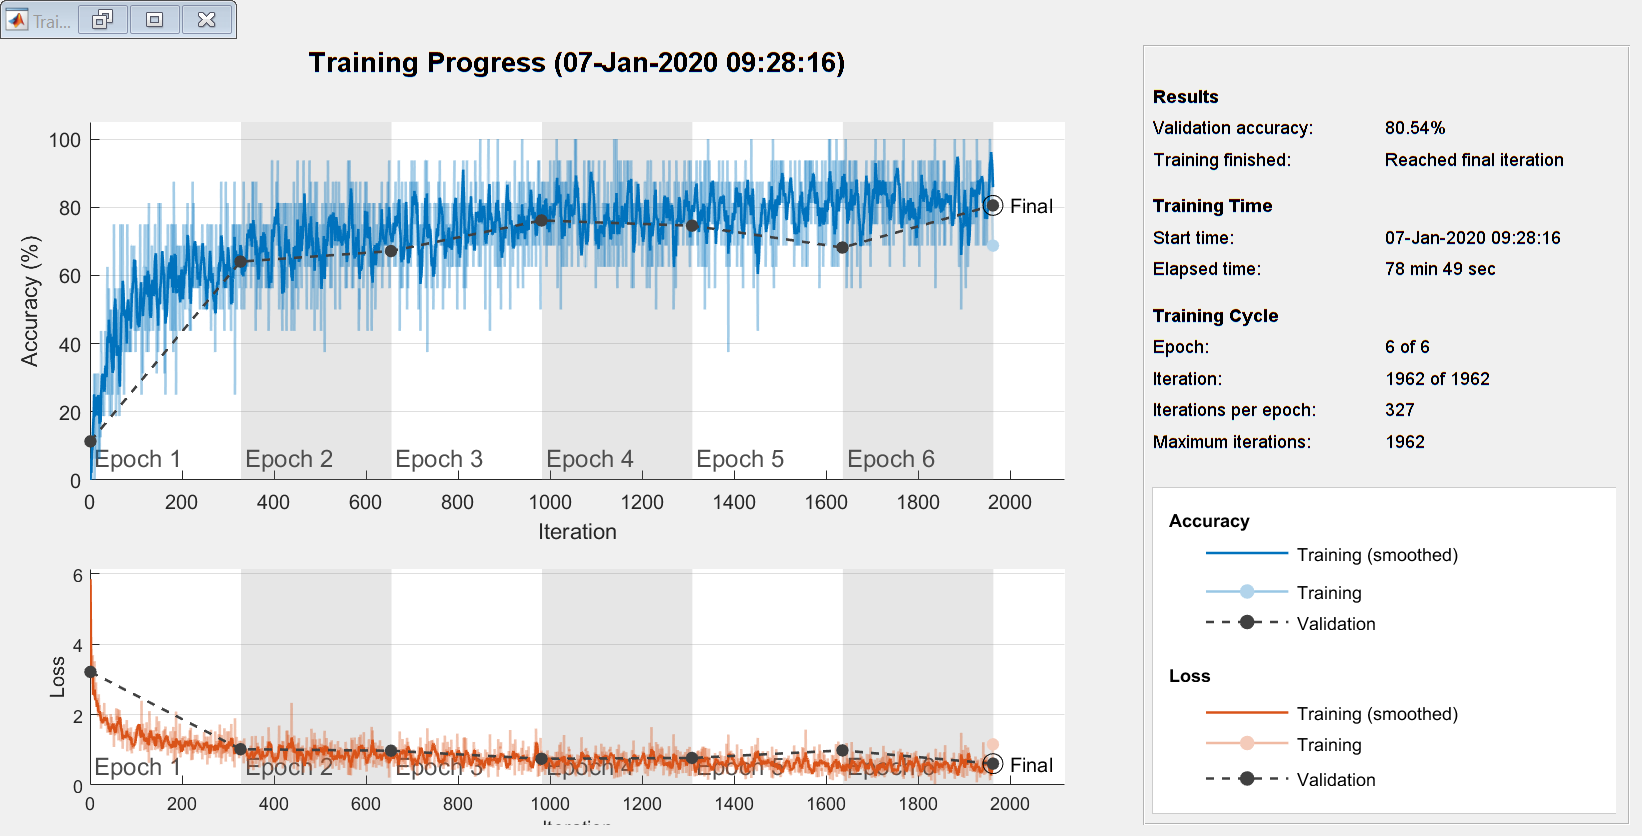

reset(gpuDevice())
net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

[YPred,probs] = classify(net,imgsTest);
accuracy = mean(YPred == imgsTest.Labels)

accuracy = 0.8031

Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels.

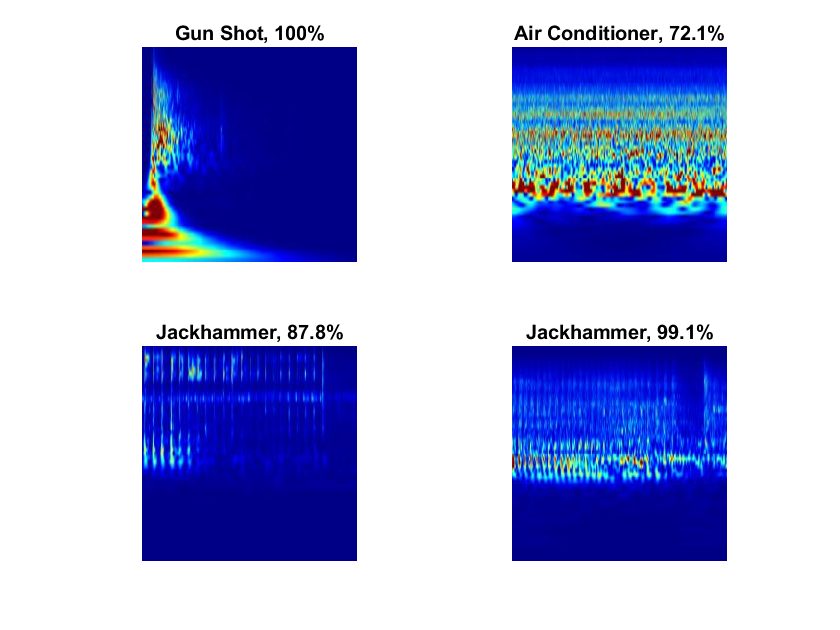

idx = randperm(numel(imgsTest.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsTest,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

## Helper Function

function helperCreateRGBfromTF(ads,datafolder_scallogram)

for i = 1:length(ads.Files)
    clearvars sig
    Fs = 44100;
    sig = audioread(ads.Files{i});
    fb = cwtfilterbank('SignalLength',length(sig),...
    'SamplingFrequency',Fs,...
    'VoicesPerOctave',4);
    cfs = abs(fb.wt(sig(:)));
    im = ind2rgb(im2uint8(rescale(cfs)),jet(128));   
    imgLoc = fullfile(datafolder_scallogram,char(ads.Labels(i)));
    imFileName = strcat(char(ads.Labels(i)),'_',num2str(i),'.jpg');
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
end
end

% findLayersToReplace(lgraph) finds the single classification layer and the
% preceding learnable (fully connected or convolutional) layer of the layer
% graph lgraph.
function [learnableLayer,classLayer] = findLayersToReplace(lgraph)

if ~isa(lgraph,'nnet.cnn.LayerGraph')
    error('Argument must be a LayerGraph object.')
end

% Get source, destination, and layer names.
src = string(lgraph.Connections.Source);
dst = string(lgraph.Connections.Destination);
layerNames = string({lgraph.Layers.Name}');

% Find the classification layer. The layer graph must have a single
% classification layer.
isClassificationLayer = arrayfun(@(l) ...
    (isa(l,'nnet.cnn.layer.ClassificationOutputLayer')|isa(l,'nnet.layer.ClassificationLayer')), ...
    lgraph.Layers);

if sum(isClassificationLayer) ~= 1
    error('Layer graph must have a single classification layer.')
end
classLayer = lgraph.Layers(isClassificationLayer);


% Traverse the layer graph in reverse starting from the classification
% layer. If the network branches, throw an error.
currentLayerIdx = find(isClassificationLayer);
while true
    
    if numel(currentLayerIdx) ~= 1
        error('Layer graph must have a single learnable layer preceding the classification layer.')
    end
    
    currentLayerType = class(lgraph.Layers(currentLayerIdx));
    isLearnableLayer = ismember(currentLayerType, ...
        ['nnet.cnn.layer.FullyConnectedLayer','nnet.cnn.layer.Convolution2DLayer']);
    
    if isLearnableLayer
        learnableLayer =  lgraph.Layers(currentLayerIdx);
        return
    end
    
    currentDstIdx = find(layerNames(currentLayerIdx) == dst);
    currentLayerIdx = find(src(currentDstIdx) == layerNames);
    
end
end